recordFile1 = "../../static/experiment/type1/78/H60-L01_to_AUM-AL20.wav";
recordFile2 = "../../static/experiment/type1/78/AUM-AL20_to_H60-L01.wav";
samplingRate = 44100;
fBegin = 2000;
fEnd = 6000;
chirpTimeMs = 100;
device1D = 0.01;
device2D = 0.01;
soundSpeed = 340;

## 原始信号

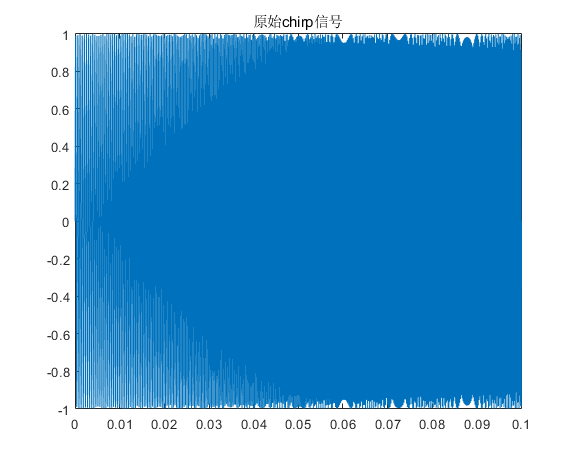

[originChirpT, originChirpY] = generateChirp(samplingRate,fBegin, fEnd, chirpTimeMs, 0);
%% 时域处理
plot(originChirpT, originChirpY);
title("原始chirp信号")

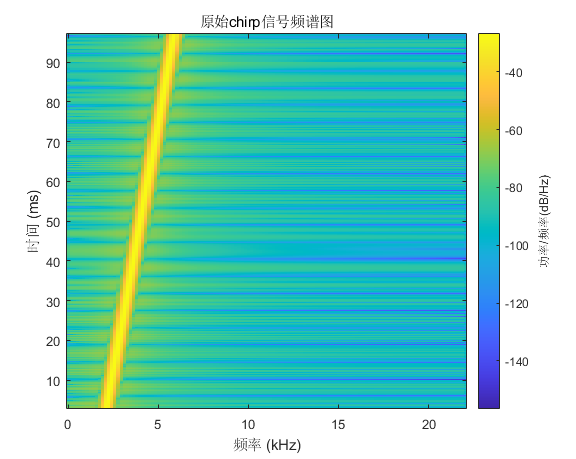

spectrogram(originChirpY, 256, 250, 256, samplingRate);
title("原始chirp信号频谱图")

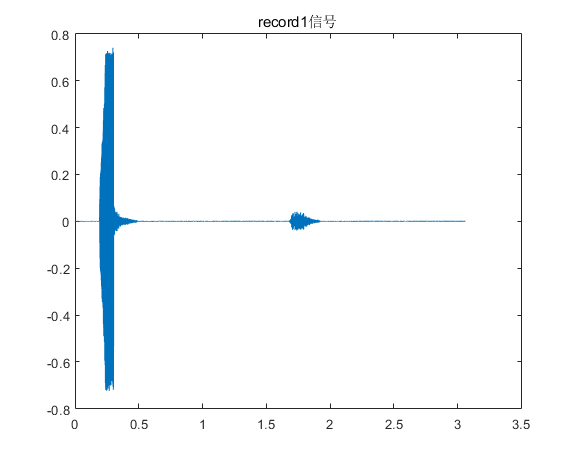



[recordY, recordFs] = audioread(recordFile1);
len1 = length(recordY);
%% 时域处理
t1 = (0:len1-1)/recordFs;
plot(t1, recordY);
title("record1信号");

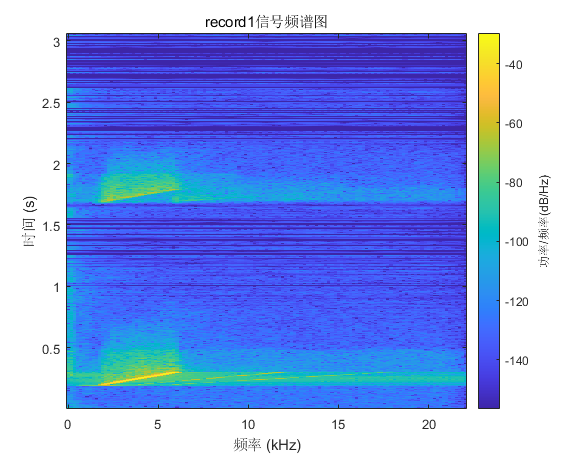

spectrogram(recordY, 256, 250, 256, samplingRate);
title("record1信号频谱图");

## 互相关

[c,lags] = xcorr(recordY, originChirpY)

c = 	1.0e+03 *

   0.000000000000000
   0.000000000000000
   0.000000000000000
  -0.000000000000000
   0.000000000000000
  -0.000000000000000
  -0.000000000000000
  -0.000000000000000
  -0.000000000000000
   0.000000000000000


lags =      -134945     -134944     -134943     -134942     -134941     -134940     -134939     -134938     -134937     -134936     -134935     -134934     -134933     -134932     -134931     -134930     -134929     -134928     -134927     -134926     -134925     -134924     -134923     -134922     -134921     -134920     -134919     -134918     -134917     -134916     -134915     -134914     -134913     -134912     -134911     -134910     -134909     -134908     -134907     -134906     -134905     -134904     -134903     -134902     -134901     -134900     -134899     -134898     -134897     -134896


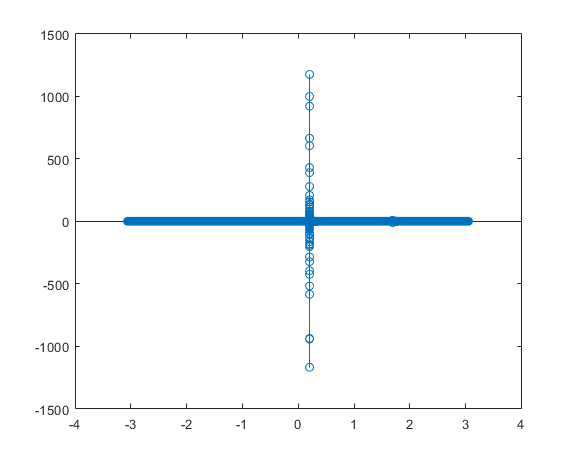

stem(lags / samplingRate, c)

% 原始信号数
stdSampleNum = length(originChirpY);

% 首先找到一个全局最大值
[maxValue, maxIndex] = max(c)

maxValue =      1.175671835947057e+03


maxIndex =       143860


rangeStart1 = maxIndex - stdSampleNum

rangeStart1 =       139449


rangeEnd1 = rangeStart1 + stdSampleNum + stdSampleNum - 1;
peak1 = lags(1, maxIndex)

peak1 =         8914


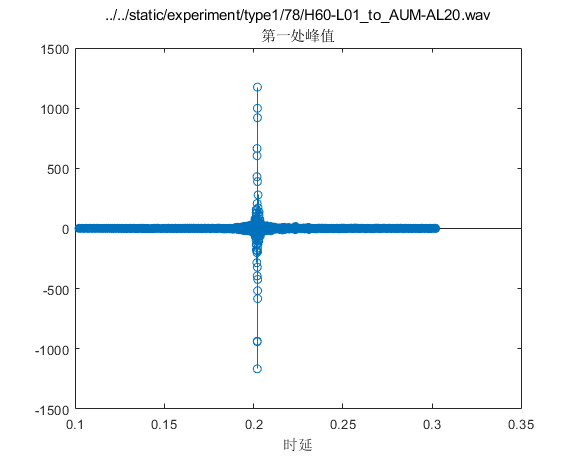

stem(lags(rangeStart1:rangeEnd1)/samplingRate, c(rangeStart1:rangeEnd1))
title({recordFile1, "第一处峰值"}, 'Interpreter', 'none')
xlabel("时延")

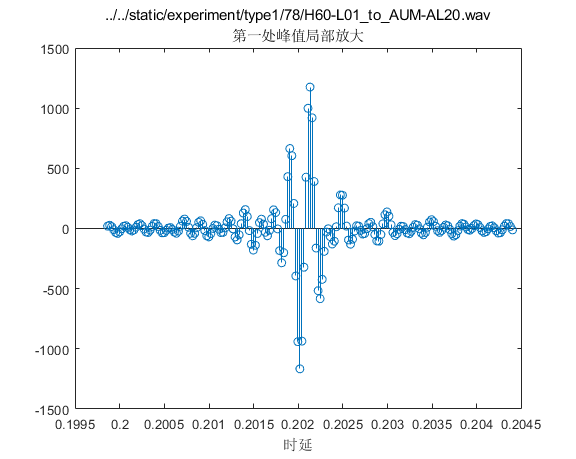

stem(lags(maxIndex-100:maxIndex+100)/samplingRate, c(maxIndex-100:maxIndex+100))
title({recordFile1, "第一处峰值局部放大"}, 'Interpreter', 'none')
xlabel("时延")

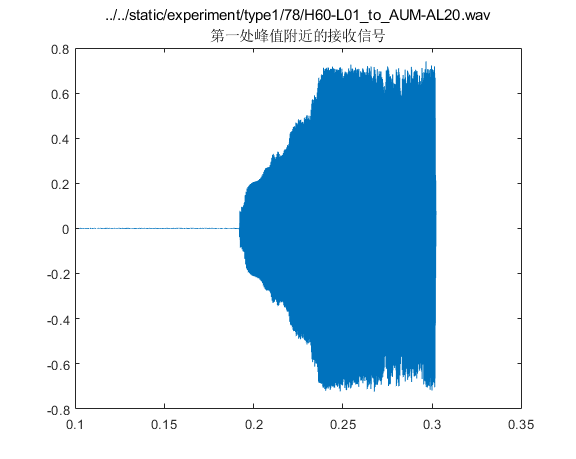



plot(t1(rangeStart1 - len1:rangeEnd1-len1), recordY(rangeStart1 - len1:rangeEnd1-len1));
title({recordFile1, "第一处峰值附近的接收信号"}, 'Interpreter', 'none');

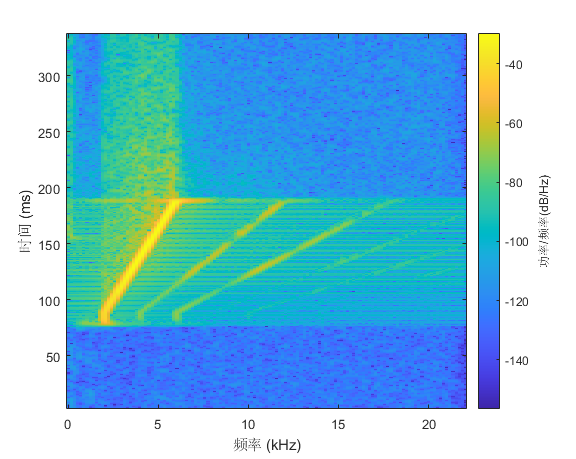

spectrogram(recordY(5000:20000), 256, 250, 256, samplingRate);


% 在其余两段中找另一个全局最大值
tmp = [c(1:rangeStart1 - 1); zeros(stdSampleNum + stdSampleNum, 1); c(rangeEnd1 + 1:length(c))]

tmp =    0.000000000000000
   0.000000000000001
   0.000000000000000
  -0.000000000000001
   0.000000000000000
  -0.000000000000002
  -0.000000000000002
  -0.000000000000000
  -0.000000000000001
   0.000000000000001


[maxValue, maxIndex] = max(tmp)

maxValue =   10.637318626404239


maxIndex =       209698


rangeStart2 = maxIndex - stdSampleNum

rangeStart2 =       205287


rangeEnd2 = rangeStart2 + stdSampleNum + stdSampleNum - 1;
peak2 = lags(1, maxIndex)

peak2 =        74752


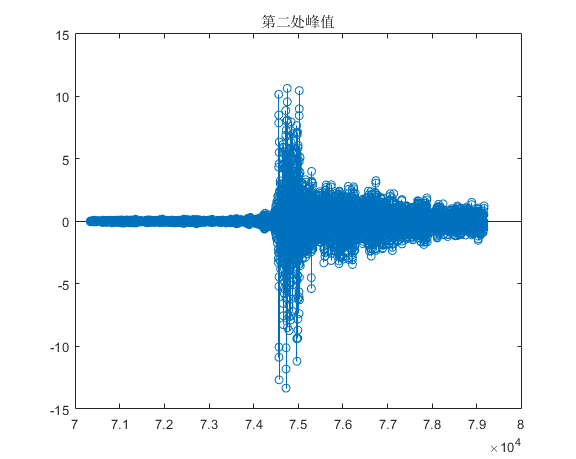

stem(lags(rangeStart2:rangeEnd2), tmp(rangeStart2:rangeEnd2))
title("第二处峰值")


format long
timeDifference = abs(peak1 - peak2) / samplingRate

timeDifference =    1.492925170068027



% computeTimeDifference(recordY, originChirpY, samplingRate)

## 计算距离

[path, name, ext] = fileparts(recordFile1)

path = "../../static/experiment/type1/78"

name = "H60-L01_to_AUM-AL20"

ext = ".wav"

 path + "/" + name + "_"

ans = "../../static/experiment/type1/78/H60-L01_to_AUM-AL20_"

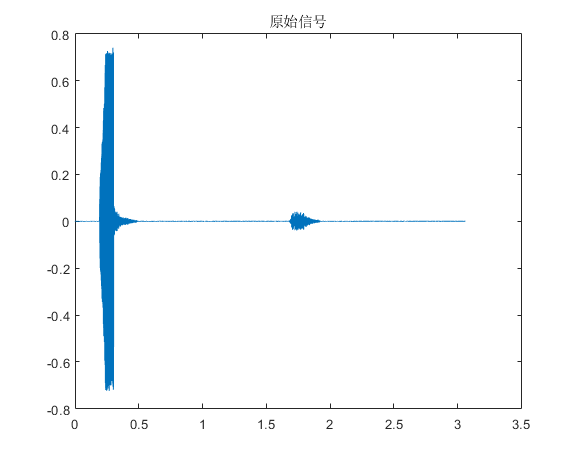

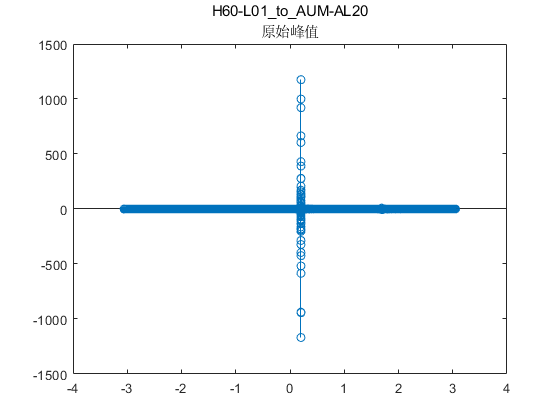

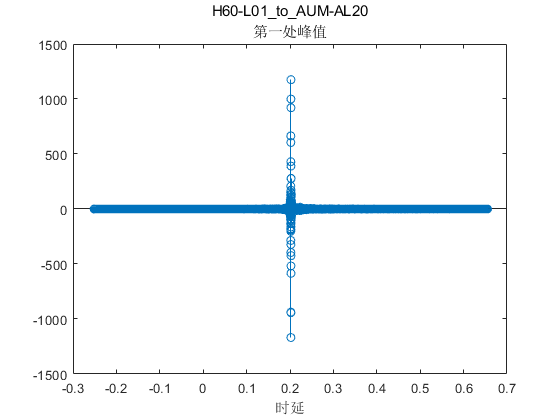

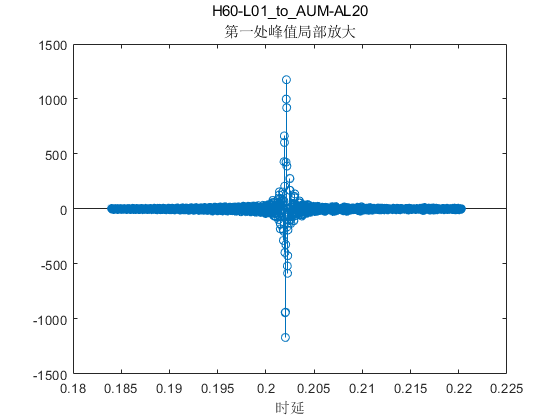

ans =    0.202131519274376


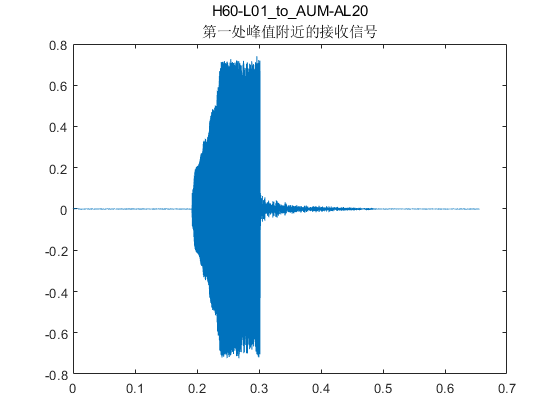

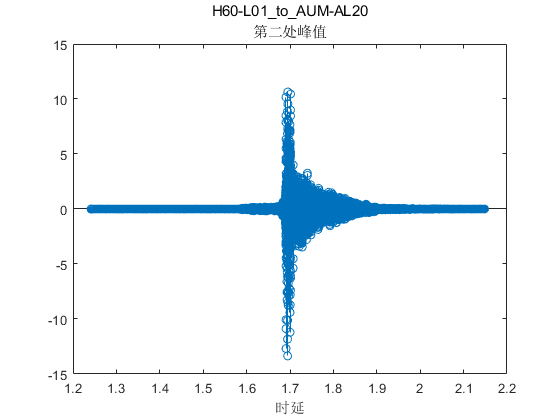

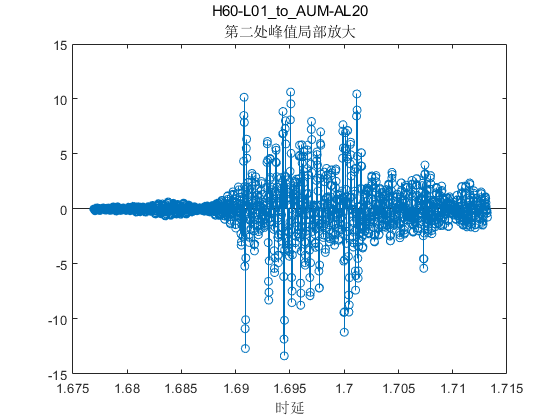

ans =    1.695056689342404


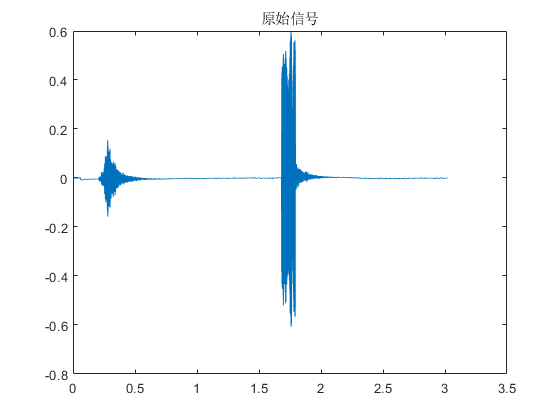

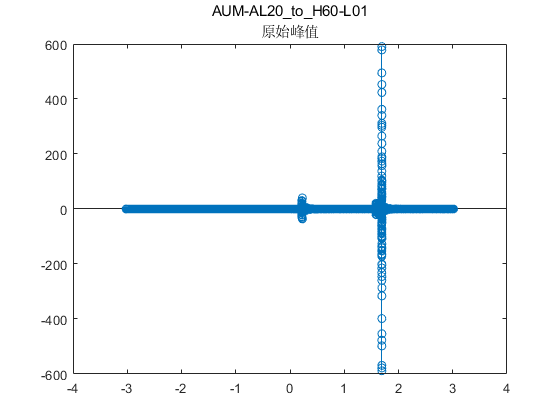

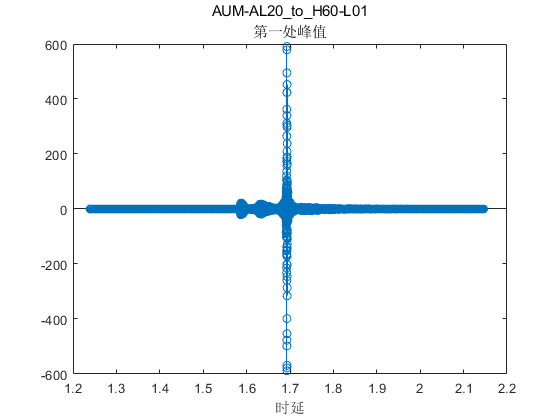

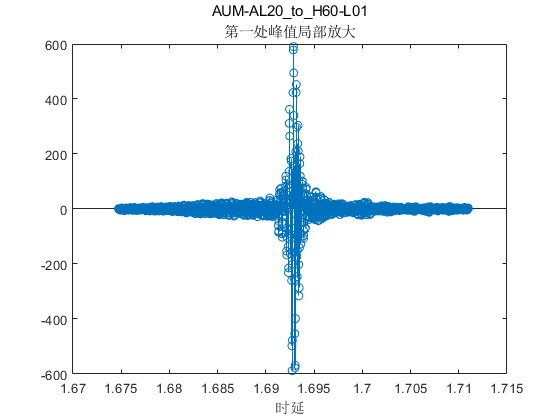

ans =    1.692857142857143


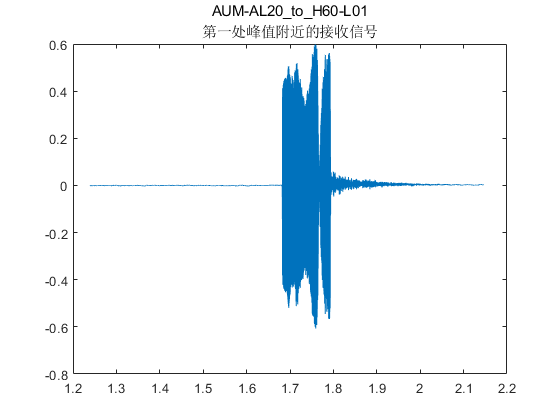

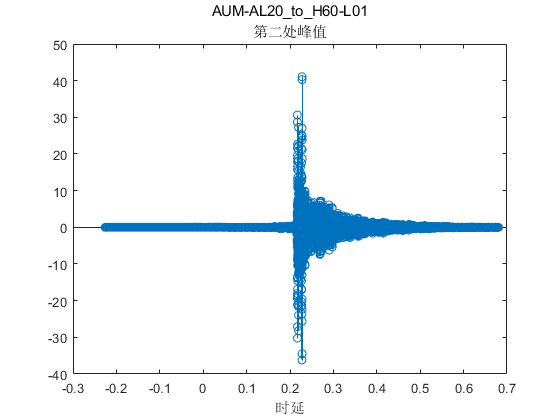

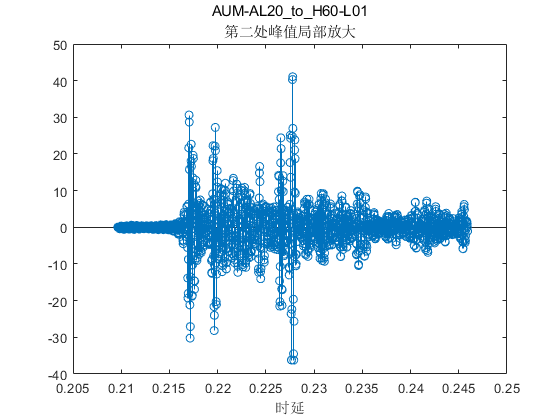

ans =    0.227777777777778


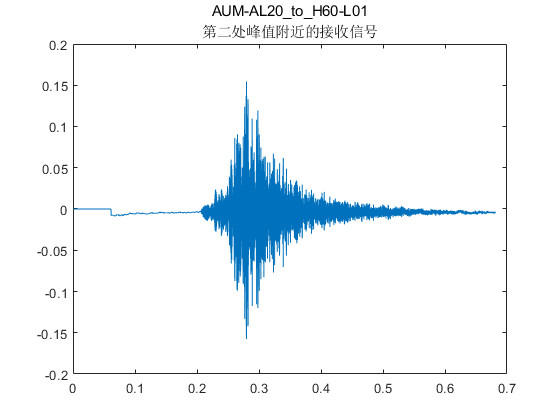

ans =    4.743786848072590


% [recordY, recordFs] = audioread(recordFile);
% td1 = computeTimeDifference(recordY, originChirpY, samplingRate)
% [recordY, recordFs] = audioread(recordFile2);
% td2 = computeTimeDifference(recordY, originChirpY, samplingRate)
% D = abs(td1 - td2) * soundSpeed / 2 + (device1D + device2D) / 2

computeDistance(recordFile1, recordFile2, device1D, device2D, samplingRate, fBegin, fEnd, chirpTimeMs, soundSpeed)